# HINF

Cargar los datos de la función de transferencia

load("../../data/TF.mat"); 

G= Gss;
USSlinmodel = Gss % createUSSmodel(G,20);

USSlinmodel =
 
  A = 
           theta   omega
   theta       0       1
   omega  -44.45  -3.334
 
  B = 
              u1
   theta       0
   omega  0.9745
 
  C = 
          theta  omega
   theta      1      0
 
  D = 
          u1
   theta   0
 
Continuous-time state-space model.



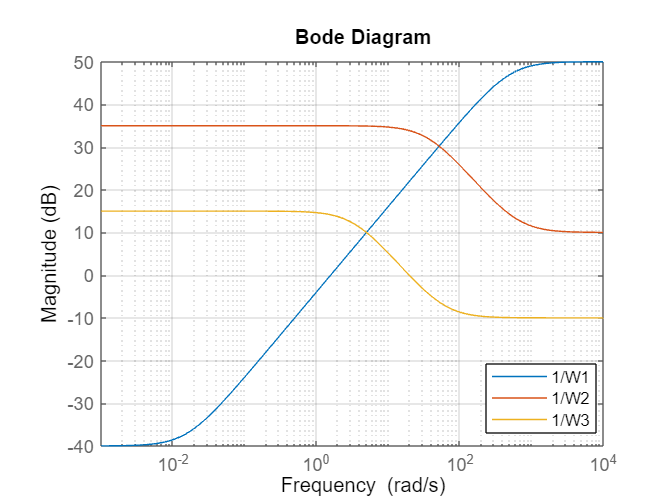



freqC1=5;freqC2=32;freqC3=5;

% Selección de filtros 
W1 = makeweight(db2mag(40),[freqC1 db2mag(-10)],db2mag(-50)); % S 
W2  =makeweight(db2mag(-35),[freqC2 db2mag(-32.5)],db2mag(-10)); % KS 
%W2 = db2mag(35*pi/180*30);
W3 = makeweight(db2mag(-15),[freqC3 db2mag(-10)],db2mag(10)); % T


bodemag(1/W1, 1/W2, 1/W3); 
legend("1/W1", "1/W2","1/W3"); 

legend("Location","best")
grid on


[K_hinf,CL,gamma] = mixsyn(G,W1,W2,W3);
gamma

gamma = 0.8624

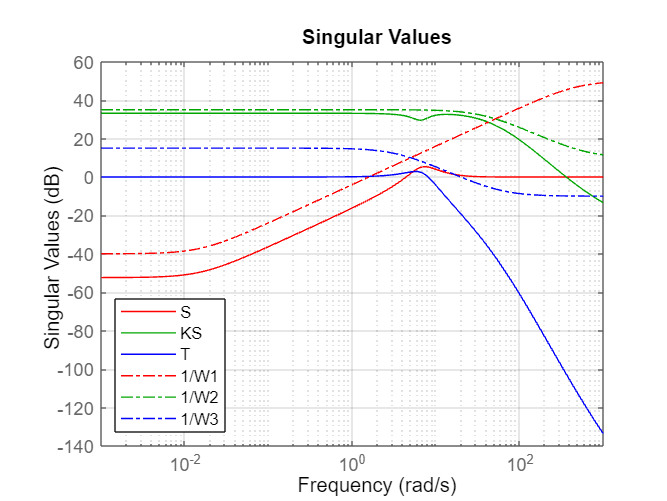

S = feedback(1,G*K_hinf);KS = K_hinf*S;T = 1-S;
sigma(S,'r',KS,'g',T,'b',1/W1,'r-.',ss(1/W2),'g-.',1/W3,'b-.',{1e-3,1e3})
legend('S','KS','T','1/W1','1/W2','1/W3','Location','SouthWest')
grid


tf(K_hinf)

ans =
 
  180.6 s^4 + 1.277e05 s^3 + 7.422e06 s^2 + 2.895e07 s + 3.107e08
  ---------------------------------------------------------------
  s^5 + 167.7 s^4 + 9443 s^3 + 1.962e05 s^2 + 1.04e06 s + 1.64e04
 
Continuous-time transfer function.



ALL W

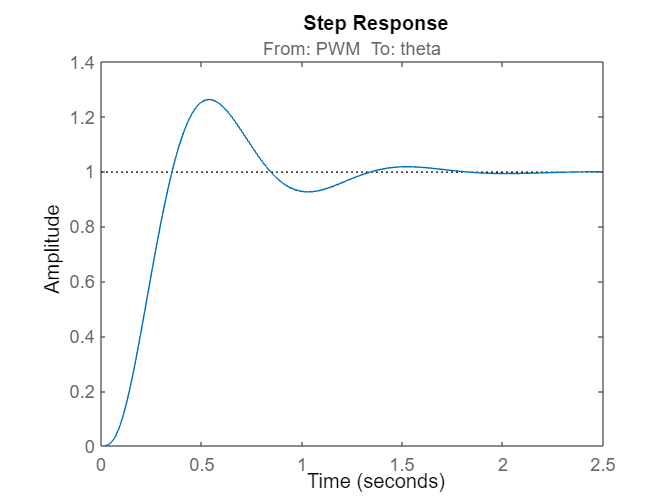

figure()
[K_hinf,CL,gamma]=mixsyn(G,W1,W2,W3);
OL=series(K_hinf,G);
GCL=feedback(OL,1);
GCL.InputName="PWM";
step(GCL)

stepinfo(GCL)

ans = struct with fields:
         RiseTime: 0.2161
    TransientTime: 1.2609
     SettlingTime: 1.2609
      SettlingMin: 0.9256
      SettlingMax: 1.2621
        Overshoot: 26.5175
       Undershoot: 0
             Peak: 1.2621
         PeakTime: 0.5408


AnchoBanda=bandwidth(GCL)/(2*pi)

AnchoBanda = 1.4975

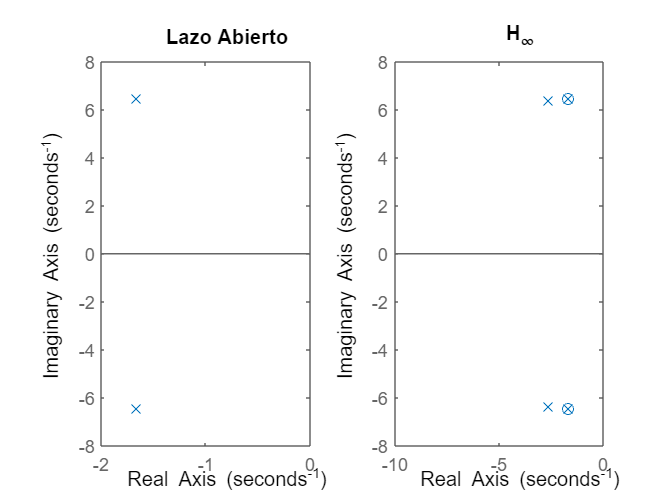


figure()
subplot(1,2,1)
pzmap(G)
title("Lazo Abierto")
subplot(1,2,2)
pzmap(GCL)
title("H_\infty")
xlim([-10 0])


pole(GCL)

ans =  -66.2070 + 0.0000i
 -60.2010 + 0.0000i
 -36.0103 + 0.0000i
  -1.6670 + 6.4552i
  -1.6670 - 6.4552i
  -2.6398 + 6.3726i
  -2.6398 - 6.3726i


### Incertidumbre

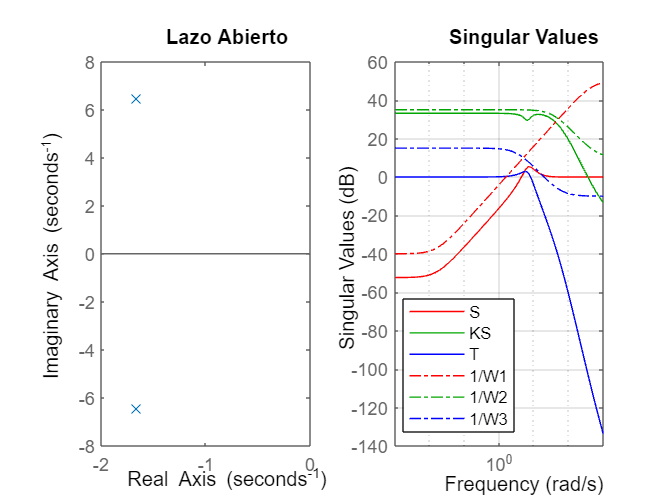

SUSS = feedback(1,USSlinmodel*K_hinf);
KSSUSS = K_hinf*SUSS;
TSUSS = 1-SUSS;
sigma(SUSS,'r',KSSUSS,'g',TSUSS,'b',1/W1,'r-.',ss(1/W2),'g-.',1/W3,'b-.',{1e-3,1e3})
legend('S','KS','T','1/W1','1/W2','1/W3','Location','SouthWest')
grid

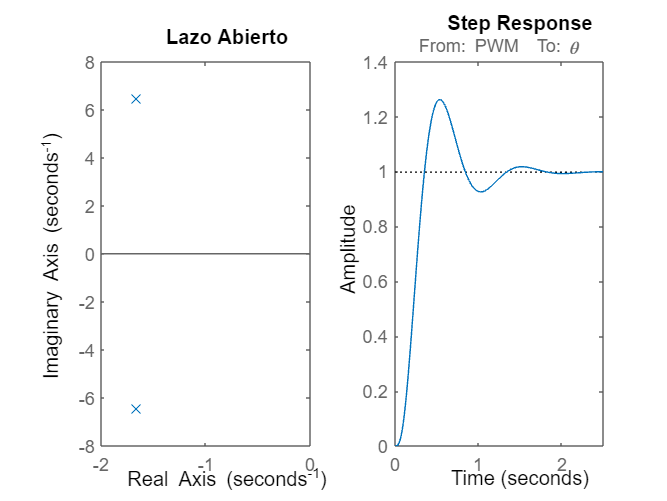


OLlinUSS=series(K_hinf,USSlinmodel);
GCLlinUSS=feedback(OLlinUSS,1);
GCLlinUSS.InputName="PWM";
GCLlinUSS.OutputName="\theta";
step(GCLlinUSS)
%axis([0 1.2 0 1.2])
hold off

bandwidth(GCLlinUSS)/2/pi

ans = 1.4975

stepinfo(GCLlinUSS)

ans = struct with fields:
         RiseTime: 0.2161
    TransientTime: 1.2609
     SettlingTime: 1.2609
      SettlingMin: 0.9256
      SettlingMax: 1.2621
        Overshoot: 26.5175
       Undershoot: 0
             Peak: 1.2621
         PeakTime: 0.5408


## Simulación Sistema Lineal

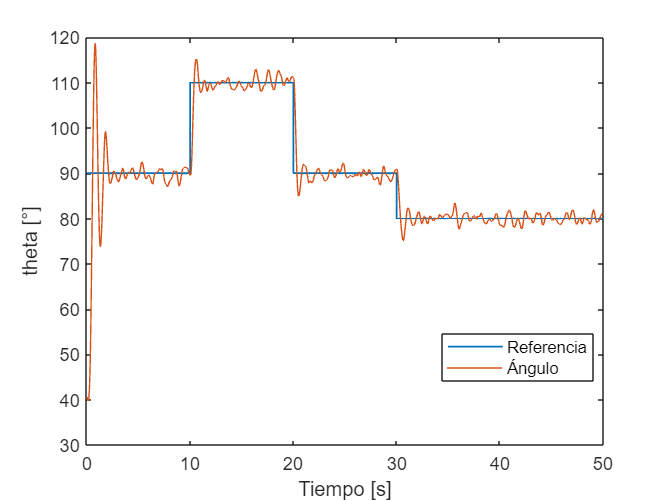

addpath("design"); 
ang_Lin = 40; 
results = sim("hinfSL.slx",50); 

t = results.tout; % tiempo de simulación    

% Estados del sistema
theta = results.theta.Data;
ref = results.Ref.Data;

figure()
plot(t,ref,'-', 'LineWidth',1); 
hold on; 
plot(t,theta);
hold off
xlabel('Tiempo [s]');
ylabel('theta [°]');
legend('Referencia', 'Ángulo','Location','best');

## Simulación Sistema No Lineal

DirectCMD = 40;
results = sim("hinfNL.slx",50); 

Invalid setting in 'hinfNL/Discrete State-Space' for parameter 'A'.

Caused by:
    Error using design
    Error evaluating parameter 'A' in 'hinfNL/Discrete State-Space'
        Error using design
        Unable to resolve the name 'HinfDiscrete.A'.


t = results.tout; % tiempo de simulación    

% Estados del sistema
theta = results.theta.Data;
ref = results.Ref.Data;

figure()
plot(t,ref,'-', 'LineWidth',1); 
hold on; 
plot(t,theta);
hold off
xlabel('Tiempo [s]');
ylabel('theta [°]');
ylim([60 120])
legend('Referencia', 'Ángulo','Location','best');

## Implementacion en arduino

Convertimos el controldador en ss a espacio discreto para agregarlo al lazo de control de implementación.

Ts = 2.5e-3;  % Tiempo de muestreo

HinfDiscrete = c2d(K_hinf, Ts, 'tustin'); 
save("Hinf", "HinfDiscrete"); 


